# MACM 203 Assignment 6

#### Part (a)

Load the data file that contains the settlements and towers coordinates.

load a6.mat

Plot a map to see the geographical distribution of settlements and potential tower locations.

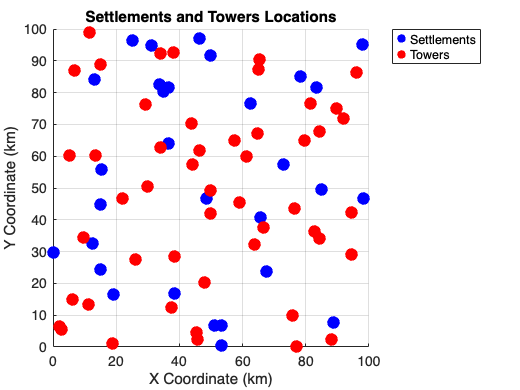

figure;
hold on;
scatter(S(:,1), S(:,2), 80, 'b', 'filled');
scatter(T(:,1), T(:,2), 80, 'r', 'filled');
xlabel('X Coordinate (km)');
ylabel('Y Coordinate (km)');
title('Settlements and Towers Locations');
legend('Settlements', 'Towers', 'Location', 'northeastoutside');
grid on;
hold off;

#### Part (b)

Initialize matrix M where M(i,j) represents the distance between settlement i and potential tower location j.

This matrix will help determine which towers can serve which settlements.

M = zeros(length(S), length(T));

Calculate the Euclidean distance between each settlement and each potential tower location. This tells us how far each settlement is from each potential tower site.

for i = 1:length(S)
    for j = 1:length(T)
        M(i,j) = norm(S(i,:) - T(j,:));
    end
end

Convert the distance matrix to a binary coverage matrix. A value of 1 means the tower can cover the settlement (distance <= 25km), and 0 otherwise.

M = M <= 25;

Create an optimization problem to minimize the number of towers while ensuring all settlements have coverage.

prob = optimproblem()

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [0x0 struct] containing 0 OptimizationVariables
         Objective: [0x0 OptimizationExpression]
       Constraints: [0x0 struct] containing 0 OptimizationConstraints

  No problem defined.


Define the decision variables. Each potential tower site is represented by a binary variable (1 = build tower, 0 = don't build).

x = optimvar('x', length(T), 'Type', 'integer', 'LowerBound', 0, 'UpperBound', 1)

x =   50x1 OptimizationVariable array with properties:

  Array-wide properties:
          Name: 'x'
          Type: 'integer'
    IndexNames: {{}  {}}

  Elementwise properties:
    LowerBound: [50x1 double]
    UpperBound: [50x1 double]

  See variables with show.
  See bounds with showbounds.


Set the objective function to minimize the total number of towers built.

prob.Objective = sum(x)

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1x1 struct] containing 1 OptimizationVariable
         Objective: [1x1 OptimizationExpression]
       Constraints: [0x0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.


Add the constraint that each settlement must be covered by at least one tower. M*x >= 1 ensures each settlement has at least one tower within range.

prob.Constraints = M*x >= 1

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1x1 struct] containing 1 OptimizationVariable
         Objective: [1x1 OptimizationExpression]
       Constraints: [30x1 OptimizationConstraint]

  See problem formulation with show.


Solve the optimization problem to find the minimum number of towers needed.

sol = solve(prob)


Solving problem using intlinprog.
Running HiGHS 1.7.0: Copyright (c) 2024 HiGHS under MIT licence terms
Coefficient ranges:
  Matrix [1e+00, 1e+00]
  Cost   [1e+00, 1e+00]
  Bound  [1e+00, 1e+00]
  RHS    [1e+00, 1e+00]
Presolving model
30 rows, 50 cols, 216 nonzeros  0s
27 rows, 26 cols, 117 nonzeros  0s
Objective function is integral with scale 1

Solving MIP model with:
   27 rows
   26 cols (20 binary, 6 integer, 0 implied int., 0 continuous)
   117 nonzeros

        Nodes      |    B&B Tree     |            Objective Bounds              |  Dynamic Constraints |       Work      
     Proc. InQueue |  Leaves   Expl. | BestBound       BestSol              Gap |   Cuts   InLp Confl. | LpIters     Time

         0       0         0   0.00%   3               inf                  inf        0      0      0         0     0.0s
 T       0       0         0   0.00%   3               6                 50.00%        0      0      0        19     0.0s

Solving report
  Status            Optima

sol = struct with fields:
    x: [50x1 double]


Determine the optimal number of towers that need to be built.

evaluate(prob.Objective, sol)

ans = 6

Extract the locations where towers should be built based on the optimization solution.

T = T(sol.x == 1, :)

T =    81.4426   76.6027
    9.7183   34.2804
   49.9726   49.3299
   94.3118   29.1977
   48.0804   20.2585
   34.1765   92.3956


#### Part (c)

Create a final visualization showing the optimized solution with settlements, selected tower locations, and coverage circles.

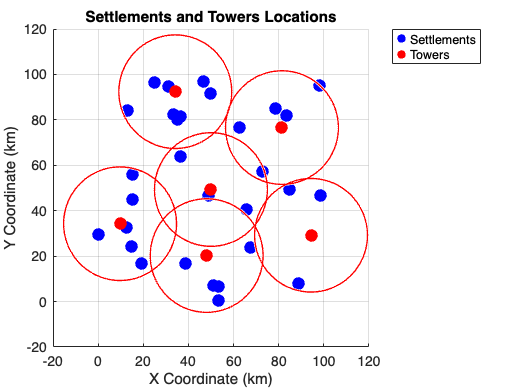

figure;
hold on;
scatter(S(:,1), S(:,2), 80, 'b', 'filled');
scatter(T(:,1), T(:,2), 80, 'r', 'filled');
viscircles(T, 25, 'LineWidth', 1);
xlabel('X Coordinate (km)');
ylabel('Y Coordinate (km)');
title('Settlements and Towers Locations');
legend('Settlements', 'Towers', 'Location', 'northeastoutside');
grid on;
hold off;